# Run a PPI analysis on a good subject

Get a good subject from the Williams/Flywheel database Pull down the 'Connect Preprocessing for PanLab pipeline data Pull out two sets of time series from two ROIs Implement/run the PPI calculation

CC,BW Scitran Team, 2017

## This is the channel to the flywheel-cni site

fw = scitran('cni');

## How our heros downloaded the relevant data from the CNI site

% The files we need are a go-no data files that are CSV
% The BOLD time series nifti

% Here is a good data set.  Why are there three sessions?
[sessions, srch] = fw.search('sessions',...
    'project label','ENGAGE', ...
    'subject code','MV09305');

% Get analyses from the first session with these names
anCPGNG2 = fw.search('analyses in session',...
    'project label','ENGAGE', ...
    'subject code','MV09305', ...
    'session id',sessions{1}.id,...
    'analysis label contains','connectivity-preprocessing (go-no-go 2)');
   
anFLMGNG2 = fw.search('analyses in session',...
    'project label','ENGAGE', ...
    'subject code','MV09305', ...
    'session id',sessions{1}.id,...
    'analysis label contains','first-level-models (go-no-go 2)');

GoFile = fw.search('files in analysis',...
    'analysis id',anFLMGNG2{1}.id,...
    'file name','Go_Onsets.csv');
fw.get(GoFile{1},'destination',fullfile(stRootPath,'local','Go.csv'));

NoGoFile = fw.search('files in analysis', ...
    'analysis id',anFLMGNG2{1}.id,...
    'file name','NoGo_Onsets.csv');
fw.get(NoGoFile{1},'destination',fullfile(stRootPath,'local','NoGo.csv'));

warpedImage = fw.search('files in analysis',...
    'session id',sessions{1}.id,...
    'analysis id',anCPGNG2{1}.id,...
    'filename','warped_files@@wa01_normalized_func_data.nii.gz');
fw.get(warpedImage{1},'destination',fullfile(stRootPath,'local','warpedImage.nii.gz'));

## Starting the analysis

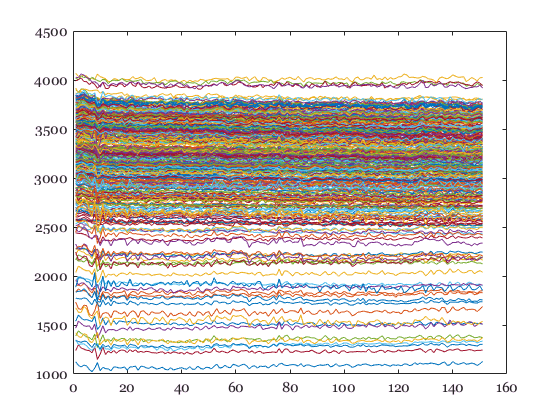


chdir(fullfile(stRootPath,'local'));

nii = niftiRead(fullfile(pwd,'warpedImage.nii.gz'));
roi1 = niftiRead(fullfile(pwd,'pl_masks','Right_10mm_DLPFC_CogCon_FI_44_34_22_cluster.nii'));
roi2 = niftiRead(fullfile(pwd,'pl_masks','biLat_10mm_dACC_CogCon_FI_0_18_46_cluster.nii'));

sz = size(roi1.data);
[i,j,k] = ind2sub(sz,find(roi1.data == 1));
nTime = size(nii.data,4);
nPts = length(i);
roi1TS = zeros(nTime,nPts);
for ii=1:nPts
    roi1TS(:,ii) = squeeze(nii.data(i(ii),j(ii),k(ii),:));
end
newGraphWin; plot(roi1TS);

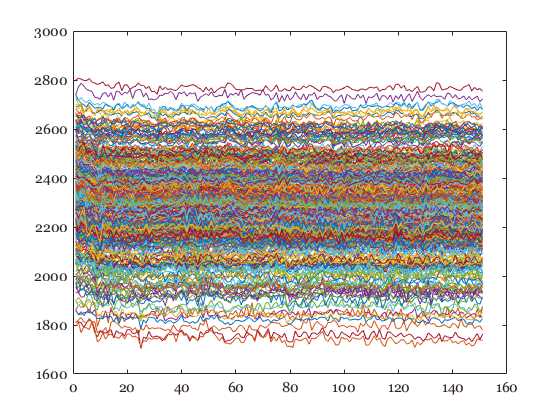

sz = size(roi2.data);
[i,j,k] = ind2sub(sz,find(roi2.data == 1));
nTime = size(nii.data,4);
nPts = length(i);
roi2TS = zeros(nTime,nPts);
for ii=1:nPts
    roi2TS(:,ii) = squeeze(nii.data(i(ii),j(ii),k(ii),:));
end
newGraphWin; plot(roi2TS);